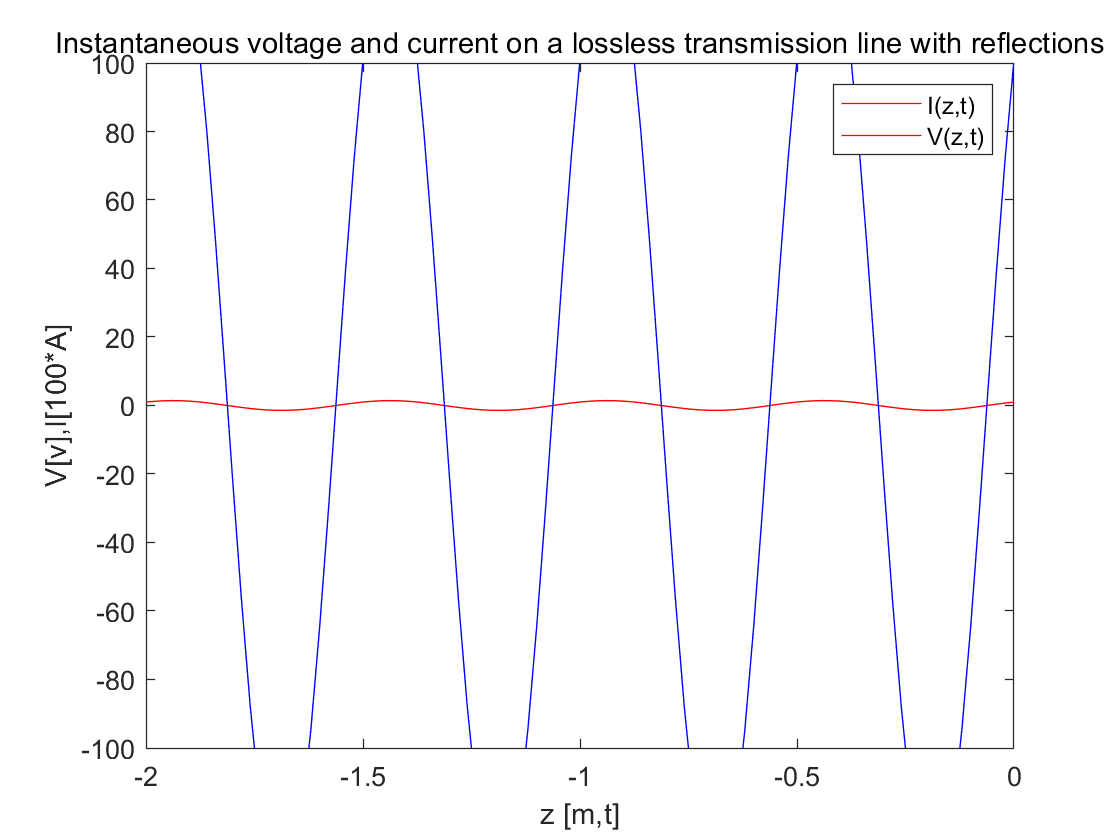

V0=1;
z = -2:0.02:0;
t = 0:0.2*10^-9:20*10^-9;
omega = 2*pi*200*10^6;
gamma = 0.05 + 2*pi*1i;
Z0 = 100;

t=repmat(t,length(z),1);
z=repmat(z',1,length(t));
GAMMA1 = 2/3;
GAMMA2 = 1;
GAMMA3 = 1i;

for GAMMA = GAMMA3
    [Vs,Is] = linephasor(V0,GAMMA,gamma,Z0,z);
    i = c_ph2inst(Is,omega,t);
    v = v_ph2inst(Vs,omega,t);
    for k=1:length(t)
    plot(z, i(k,:), 'r');  hold on;
    plot(z, v(k,:), 'b');  hold off;
    xlabel('z [m,t]');
    ylabel('V[v],I[100*A]');
    title('Instantaneous voltage and current on a lossless transmission line with reflections');
    legend('I(z,t)', 'V(z,t)');
    axis([-2 0 -100 100]);
    M(k)=getframe;
    end
end
movie(M);

function [Vs,Is] = linephasor(V0,GAMMA,gamma,Z0,z)
Vs = (V0)*exp(-gamma*z) - GAMMA*(V0)*exp(gamma*z); 
Is = (V0/Z0)*exp(-gamma*z) - GAMMA*(V0/Z0)*exp(gamma*z); 
end
function [v]= v_ph2inst(Vs,omega,t)
v = real(Vs*exp(1i*omega*t));
end
function [i]= c_ph2inst(Is,omega,t)
i = real(Is*exp(1i*omega*t));
end